# FEM2D: Thermal problem with Convection BC using Triangular Elements

Taken from Toni Susin's [Numerical Factory 2019](https://numfactory.upc.edu/web/FiniteElements/Pract/P8-FEM2D/P8.3.FEM2DThermalTriangConvectionSmall/P8.3.FEM2DThermalTriangConvectionSmall.html).

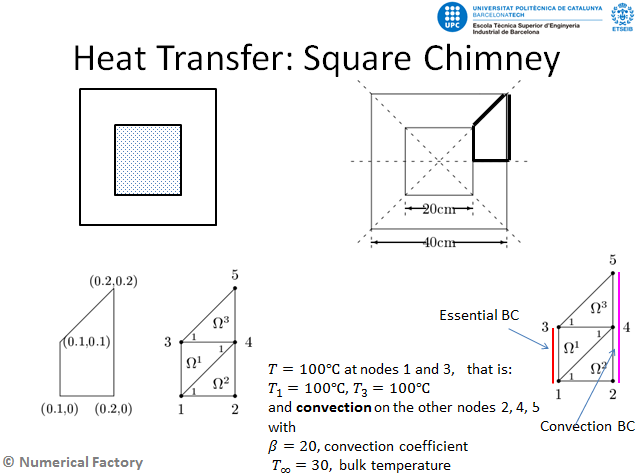

Assume $k_{c} = a_{11} = a_{22} = 1$, $a_{12}=a_{21}= a_{00} = f = 0$, so we consider the thermal equation $-\frac{\partial^{2} u}{\partial x^{2}}-\frac{\partial^{2} u}{\partial y^{2}} = 0$, with the B.C. shown in the figure above.

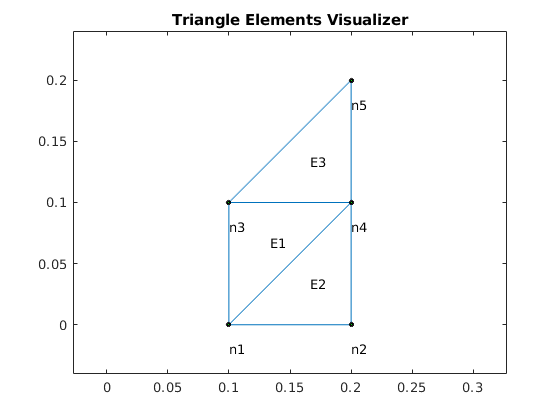

clearvars
close all

a11=1.0;
a12=0.0;
a21=a12;
a22=a11;
a00=0.0;
f=0.0;

T=100.0;
beta=20;
Tinf=30;

nodes=[
    0.1,0.0;
    0.2,0.0;
    0.1,0.1;
    0.2,0.1;
    0.2,0.2
    ];
elem=[
    4,3,1;
    1,2,4;
    3,4,5;
    ];
numNod=size(nodes,1);
numElem=size(elem,1);

numbering=1;
plotElements(nodes, elem, numbering)

%Assemble system
K=zeros(numNod);
Q=zeros(numNod,1);
F=zeros(numNod,1);

coeff=[a11,a12,a21,a22,a00,f];

for e=1:numElem
    [Ke,Fe]=linearTriangElement(coeff,nodes,elem,e);
    rows=elem(e,:);
    cols=rows;
    K(rows,cols) = K(rows,cols) + Ke;
    if coeff(6) ~= 0
        F(rows) = F(rows) + Fe;
    end
end
Kini = K; %save a copy of the stifness matrix for the post porcess

% B.C.
fixedNod=[1,3];
freeNod=setdiff(1:numNod,fixedNod);

%---------Natural B.C. 
% In this example, due to convection
nodesConv=[2,4,5];
[K,Q]=applyConvTriang(nodesConv,beta,Tinf,K,Q,nodes,elem);

%--------Essential B.C.
u=zeros(numNod,1); 
u(fixedNod)=T;

%Reduced system
Im = F(freeNod) + Q(freeNod) - K(freeNod,fixedNod)*u(fixedNod);
Km=K(freeNod,freeNod);

%Solve the reduced system
um=Km\Im;
u(freeNod) = um;

%Post porcess: compute Q's, table and contour plot
Q=Kini*u-F;

table.Nod=int32((1:numNod)');
table.X=nodes(:,1);
table.Y=nodes(:,2);
table.U=u;
table.Q=Q;

format short e
struct2table(table)

ans = 5×5 table
    Nod        X             Y             U              Q     
    ___    __________    __________    __________    ___________

     1     1.0000e-01    0.0000e+00    1.0000e+02     2.3384e+01
     2     2.0000e-01    0.0000e+00    5.3232e+01    -2.2928e+01
     3     1.0000e-01    1.0000e-01    1.0000e+02     4.7679e+01
     4     2.0000e-01    1.0000e-01    5.2321e+01    -3.8568e+01
     5     2.0000e-01    2.0000e-01    3.3189e+01    -9.5662e+00


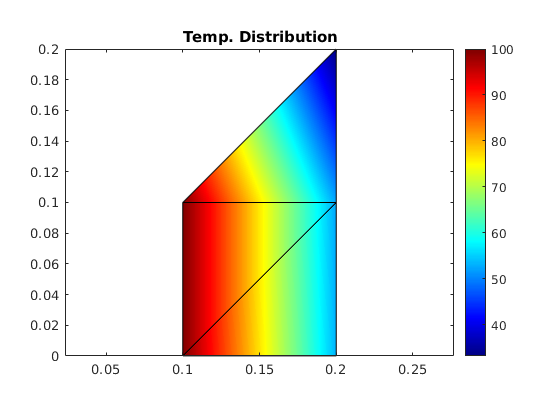


colorScale='jet';
title='Temp. Distribution';
plotContourSolution(nodes,elem,u,title,colorScale);